This script describe how to run the simulation of FLP experiments to look at how well our program deals with background correction in fitting as well as calculation of empirical lifetime. By adding different amount of background noise into the simulated histograms and letting them run through our fitting and calculation pipeline, we will compare the **spc.fit.backcorr** term with our added background and evaluate how well our program is able to resolve the background. We will also look at whether and how different size of sample (photon count) influence the performance

First I'll generate the population of Ach sensor photons based on empirically collected fitting parameters. Here we will assume the Ach sensor fluorescence follows double exponential decay.

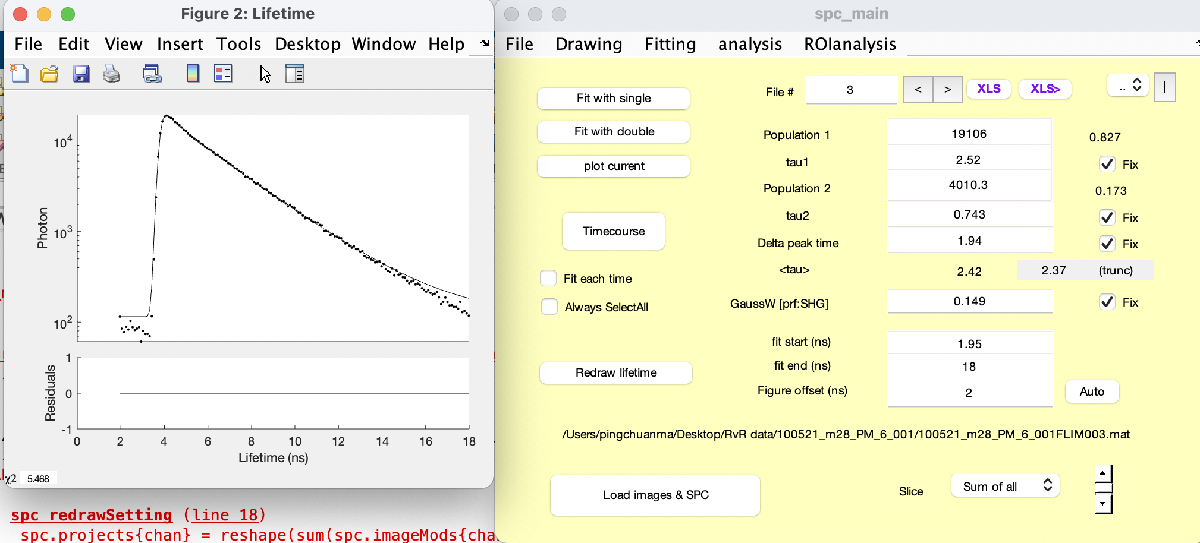

Modifications on the function GenPop256:

- Histogram span is 25 ns instead of 12.5 ns.

- Based on prf (yaochen/Active/Pingchuan/FLP_prf_031821_PM.mat), peak channel is now 37.

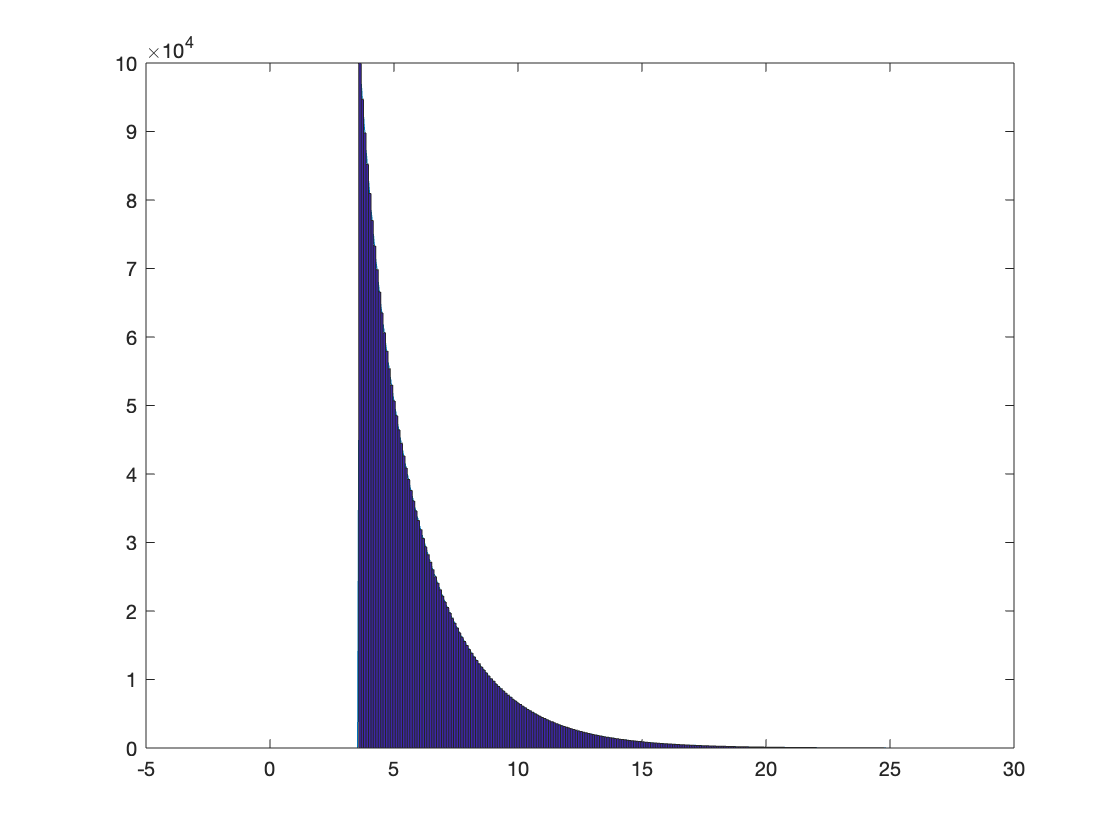

     2304890



tau1=2.5186; tau2=0.7425; p1=0.8265; p2=0.1735; TP=100000; % Peak photon 100000
GenPop256_FLP(TP,p1,p2,tau1,tau2);

load('DoubleExpPop256.mat');
save('DoubleExpPop256_FLP_1019','Population');

This section is to sample the histograms to mimick empirically collected data from FLP experiments.

What's new is that I need autofluorescence from FLP and do gaussion fitting, instead of prf fitting that I have been doing for FLIM simulation.

For gaussian fitting, I just need to generate a gaussian curve to replace the prf curve in the simulation function. The problem is what the sigma should be for the gaussian curve.